## Computer Exercises 1 - EPFL 2024

#### Hugo Penichou

#### Matthieu Scharffe

clc
clear all
close all

## 2.1 Multiplicative uncertainty

%% miscellaneous variables and plotting setup 

Ts = 0.002 ; % sampling time in s 
freqs = (pi/4096:pi/4096:pi) / Ts ; 

opts = nyquistoptions; 
opts.ConfidenceRegionDisplaySpacing = 3;
opts.ShowFullContour = 'off';

%% load data
% Define the list of files
files = {'Data/logs_1.mat', 'Data/logs_3.mat', 'Data/logs_5.mat', ...
         'Data/logs_7.mat', 'Data/logs_9.mat', 'Data/logs_11.mat'};


Let's start by identifying the model for the first set of data

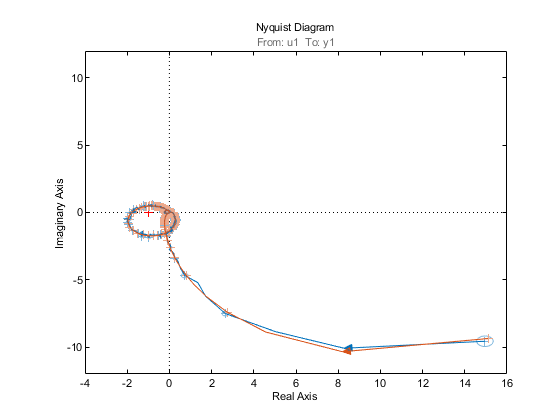

%% load data and identify the model 

% intitialization (identify model with first file)
load( files{1} )
G_current = oe(data , [8, 8, 1] ) ; 
Gf_current = spa(data, 8191, freqs) ; 
G = stack( 1 , G_current ) ; 
Gf = stack( 1 , Gf_current ) ; 

nyquistplot ( Gf , G , freqs , opts , 'sd' , 2.45) ;

The uncertainties of the parametrical model have elliptical shape. It means that the associated covariance matrix is not symmetrical.

Let's do the same thing on all the data

for idx = 2:length(files)
    disp(files{idx});
    load( files{idx} ) ; 
    G_current = oe(data , [8, 8, 1] ) ; 
    Gf_current = spa( data , 8191 , freqs ) ; 
    G = stack( 1 , G , G_current ) ; 
    Gf = stack( 1 , Gf , Gf_current ) ; 
end

Data/logs_3.mat
Data/logs_5.mat
Data/logs_7.mat
Data/logs_9.mat
Data/logs_11.mat


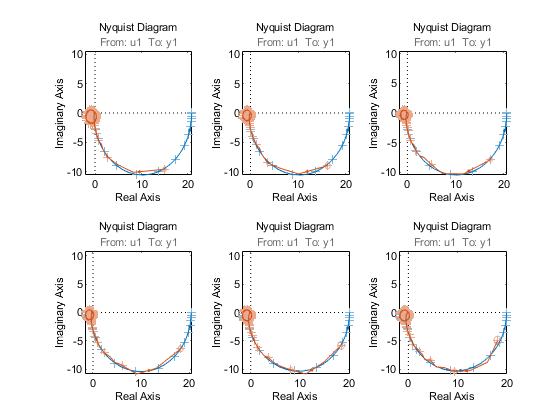


figure(1)

for i = 1:length(G)
    subplot( 2 , 3 , i )
    nyquistplot( G(:,:,i,:) , Gf(:,:,i,:) , opts , 'sd' , 2.45 ) ; 
end

[~, info1] = ucover( G , G(:,:,1,:) , 4 ) ;
W_current = info1.W1 ; 
n_inf_current = norm( W_current , inf ) ; 

W = stack( 1 , W_current ) ; 
n_inf = n_inf_current ; 

for i = 2:length(G)
    [~, info1] = ucover( G , G(:,:,i,:) , 4 ) ;
    W_current = info1.W1 ;  
    n_inf_current = norm( info1.W1opt , inf ) ; 
    W = stack( 1 , W , W_current ) ; 
    n_inf = [n_inf , n_inf_current] ;
end

chosen_one = find( n_inf == max( n_inf ) ) ; 

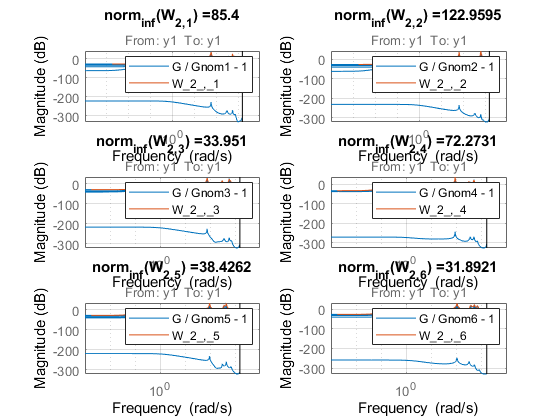

figure(2)
for i = 1:length(G)
    nom_S = strcat( 'G / Gnom' , num2str( i ) , ' - 1' ) ;
    W_S = strcat( 'W_2_,_' , num2str( i ) ) ;
    subplot(3, 2, i)
    bodemag( G / G(:,:,i,:) - 1 , W(:,:,i,:) ) ; grid on ; legend( nom_S , strcat(W_S) ) ; 
    title( strcat( 'norm_{inf}(', W_S , ') = ', num2str( n_inf(i) ) ) )
end

We should pick the model which gives the lowest infinite norm values for the uncertainty filter. This means that we pick the model 11 as the nominal one.

## 2.2  Model-based H∞ control design

### define W1 filter


s=tf('s'); m=0.505; omega_b=1000 ;
W1s=m*(s+omega_b)/(s+1e-5) ;
W1d=c2d(W1s,Ts,'zoh') ;

### compute H_inf controller

Gnom = G( : , : , chosen_one , 1 ) ;
W2n = W( : , : , chosen_one , 1 ) ; 
[ K , ~ , ~ ] = mixsyn( Gnom , W1d , [] , W2n ) ;

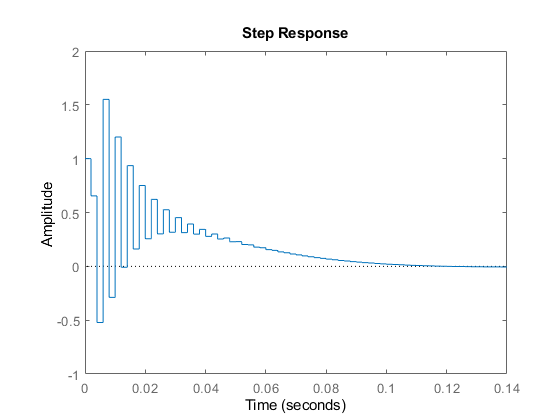

S = feedback( 1, Gnom * K ) ;
T = feedback( Gnom * K , 1 ) ;
U = feedback( K , Gnom ) ;

figure(3)
step(S);

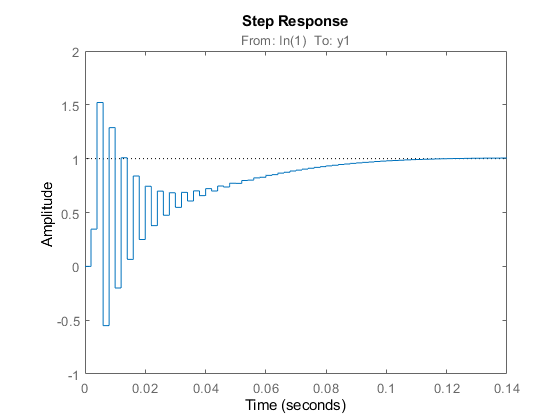

step(T);

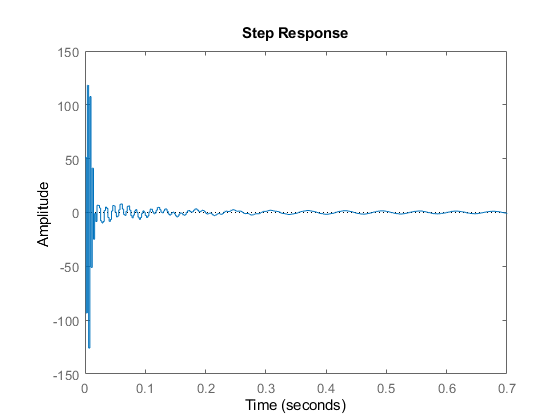

step(U);

### ADD W3 filter


W3=15;

[K,CL,gamma] = mixsyn( Gnom , W1d , W3 , W2n ) ;

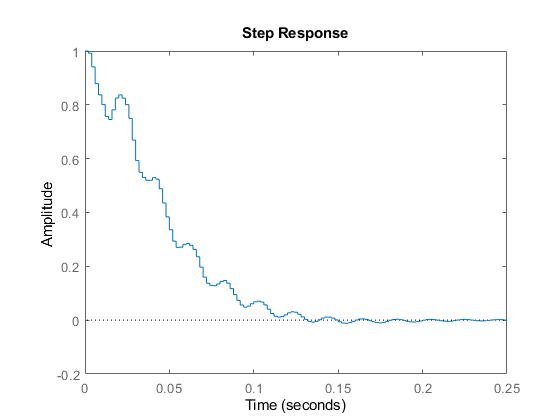

S = feedback( 1 , Gnom * K ) ;
T = feedback( Gnom * K , 1 ) ;
U = feedback( K , Gnom ) ;
figure(3)
step(S);

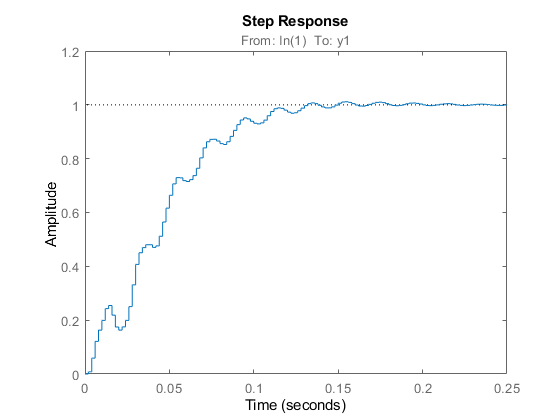

step(T);

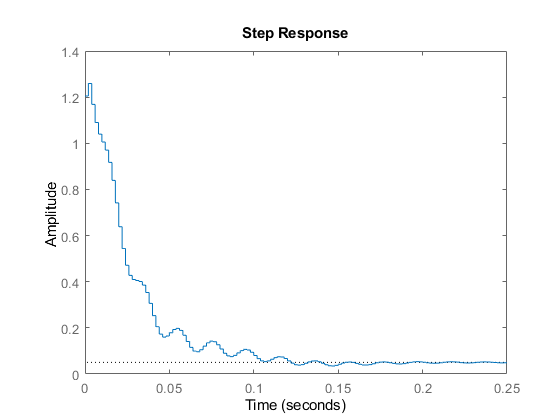

step(U);

## H2 controler